clear all
close all

addpath('classes')

### Simulation

dt = 0.5;
t_end = 25;
t = 0:dt:t_end;

x0 = [1;1;0];


robot_num = 3;
robot_set = repmat(Robot_w_communication.empty, robot_num, 1);
robot_sensor_values = [];
robot_connection_values = [];

sensor_variances    = [0.3; 0.3; 0.3];   %  variances = [v_abs; v_r; v_t]
sensor_limits       = [3; 3];            %  max_distances = [max_z_r; max_z_t]
connection_data     = [2; 0.3];          %  [max_conn_distance; connection_fail_prob]

for j = 1:robot_num
    x0 = [  -1 + 2*rand;
            -1 + 2*rand;
            -pi + 2*pi*rand;];

    robot_set(j) =  Robot_w_communication(x0,j,sensor_variances,sensor_limits,connection_data);
end

for i = 1:length(t)
    % update robot position
    for j = 1:robot_num
        robot_set(j) = robot_set(j).update(dt);
    end

    % update robot sensor readings
    for j = 1:robot_num
        robot_set(j) = robot_set(j).update_robot_measurements(robot_set,t(i));
    end

    % update robot communication
    for j = 1:robot_num
        robot_set(j) = robot_set(j).update_communications(robot_set,t(i));
    end

    robot_sensor_values = [ robot_sensor_values; robot_set(1).z_r ];
    robot_connection_values = [ robot_connection_values; robot_set(1).data_rel ];
end

### Graphs

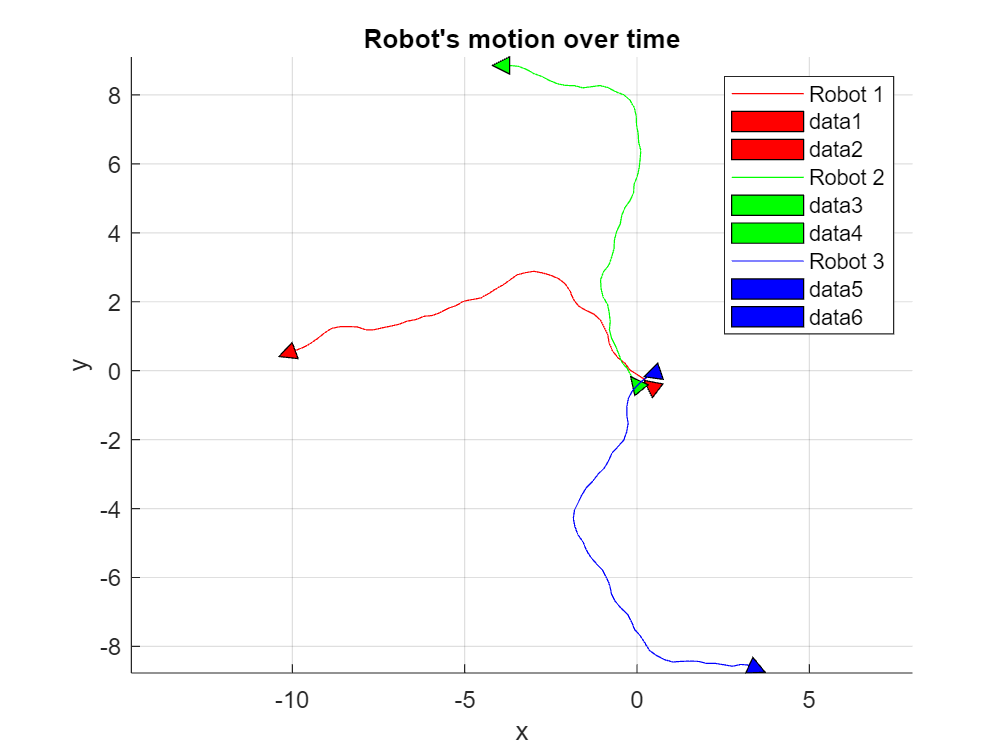

myColormap = hsv(robot_num);

figure;
hold on; axis equal;
for j = 1:robot_num
    plot(robot_set(j).true_Path(:,1), robot_set(j).true_Path(:,2), 'Color', myColormap(j,:), 'DisplayName', sprintf('Robot %d', j));
    triangle = robot_set(j).draw(1);
    patch(triangle(1,:), triangle(2,:), myColormap(j,:));
    triangle = robot_set(j).draw(length(robot_set(j).true_Path(:,1)));
    patch(triangle(1,:), triangle(2,:), myColormap(j,:));
end


xlabel('x');
ylabel('y');
title("Robot's motion over time");
legend;
% border_value = 10
% xlim([-border_value border_value])
% ylim([-border_value border_value])
grid on; hold off

robot_sensor_values

robot_sensor_values = 29×4 table
    Name    Distance    Direction    Time
    ____    ________    _________    ____

     2       0.73329       0.3817      0 
     3       0.43928        -1.41      0 
     2       0.17582      0.50338    0.5 
     3       -0.2906      -1.8314    0.5 
     2      0.038825    -0.040748      1 
     3       0.37939      -3.7138      1 
     2       0.63145      0.18572    1.5 
     3       0.63458       -3.923    1.5 
     2       0.44546     -0.27725      2 
     3       0.65517      -4.0124      2 
     2       0.14575     -0.49347    2.5 
     3        1.3101      -3.8018    2.5 
     2       0.62747     -0.23972      3 
     3        1.5877      -3.5712      3 
     2        0.5683      0.13693    3.5 
     3        2.4975      -2.8262    3.5 


robot_connection_values

robot_connection_values = 18×4 table
    Name     Distance    Direction    Time
    _____    ________    _________    ____

    {[2]}     0.64103      -2.623       0 
    {[3]}     0.73844     0.93321       0 
    {[2]}     0.44733      -2.252     0.5 
    {[3]}    0.043433      4.1128       1 
    {[2]}     0.34418     -3.0145     1.5 
    {[3]}     0.70587      3.8907     1.5 
    {[2]}    -0.10721     -3.0145       2 
    {[2]}     -0.3989     -3.2101     2.5 
    {[3]}      1.3383      3.5616     2.5 
    {[2]}      0.1517     -3.4849       3 
    {[2]}     0.61988     -2.3701     3.5 
    {[2]}     0.58911     -3.7588       4 
    {[2]}     0.29233     -3.4326     4.5 
    {[2]}     0.67945     -4.0821       5 
    {[2]}     0.69591      -3.653       6 
    {[2]}       1.135     -3.2697       7 
